# **Nolinear Truss Pushover Analysis**

First, instantiate the OpenSeesMatlab interface class. This class provides native OpenSees commands, as well as additional visualization, pre/post-processing, and utility methods.

clc; clear;

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

### Create model

ops.wipe();
ops.model("basic", "-ndm", 2, '-ndf', 2);

% variables
A = 4.0;
E = 29000.0;
alpha = 0.05;
sY = 36.0;
udisp = 2.5; 
Nsteps = 1000;
Px = 160.0;
Py = 0.0;

% create nodes
ops.node(1, 0.0, 0.0);
ops.node(2, 72.0, 0.0);
ops.node(3, 168.0, 0.0);
ops.node(4, 48.0, 144.0);

% set boundary condition
ops.fix(1, 1, 1);
ops.fix(2, 1, 1);
ops.fix(3, 1, 1);

% define materials
ops.uniaxialMaterial('Hardening', 1, E, sY, 0.0, alpha / (1 - alpha) * E);

% define elements
ops.element('Truss', 1, 1, 4, A, 1);
ops.element('Truss', 2, 2, 4, A, 1);
ops.element('Truss', 3, 3, 4, A, 1);

% create TimeSeries
ops.timeSeries('Linear', 1);

% create a plain load pattern
ops.pattern('Plain', 1, 1);

% Create the nodal load
ops.load(4, Px, Py);

### `Start of analysis generation`

% create SOE
ops.system('ProfileSPD');
% create DOF number
ops.numberer('Plain');
% create constraint handler
ops.constraints('Plain');
% create integrator
ops.integrator('LoadControl', 1.0 / Nsteps);
% create algorithm
ops.algorithm('Newton');
% create test
ops.test('NormUnbalance', 1e-8, 10, 0);
% create analysis object
ops.analysis("Static");

### `Finally perform the analysis`

data = zeros(Nsteps + 1, 2);

for j = 1:Nsteps
    ops.analyze(1);
    data(j + 1, 1) = ops.nodeDisp(4, 1);
    data(j + 1, 2) = ops.getLoadFactor(1) * Px;
end

### Model Visualization

[OpenSeesMatlab] Model summary
  Nodes: 4
  Truss elements: 3


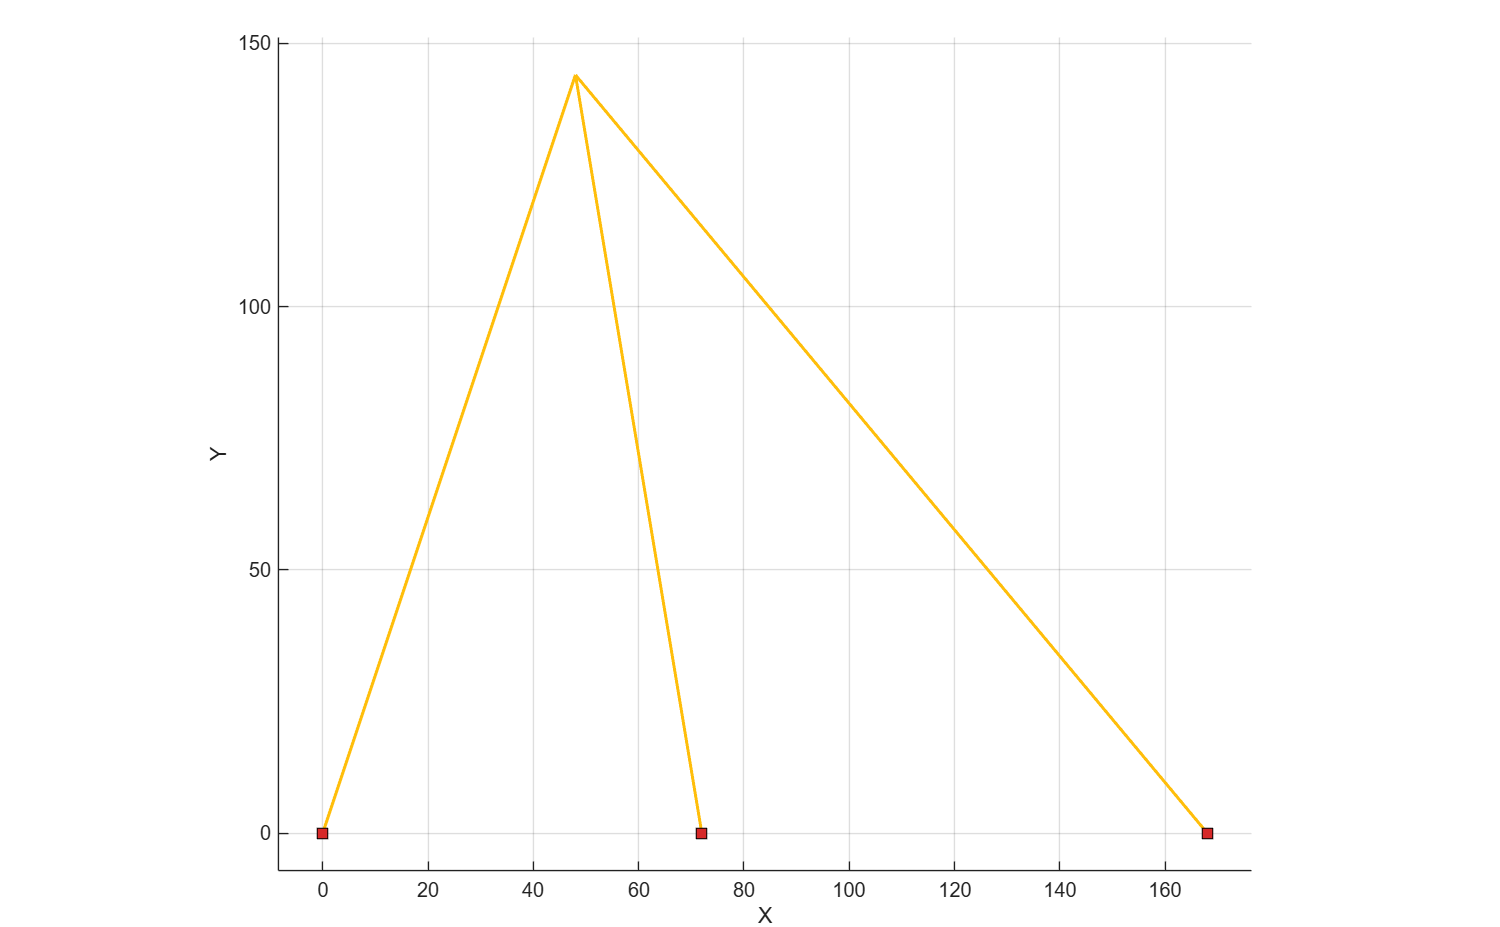

opsMAT.vis.plotModel();

### Plot

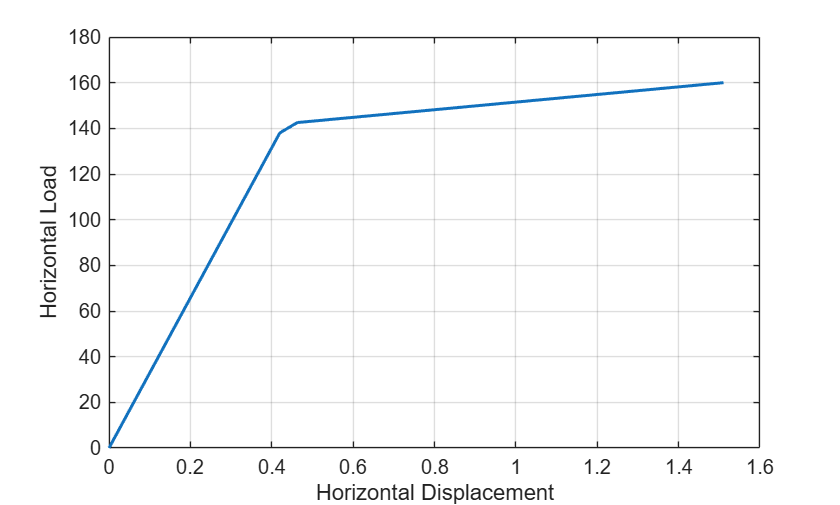

figure;
plot(data(:, 1), data(:, 2), 'LineWidth', 1.5);
xlabel('Horizontal Displacement');
ylabel('Horizontal Load');
grid on;